# 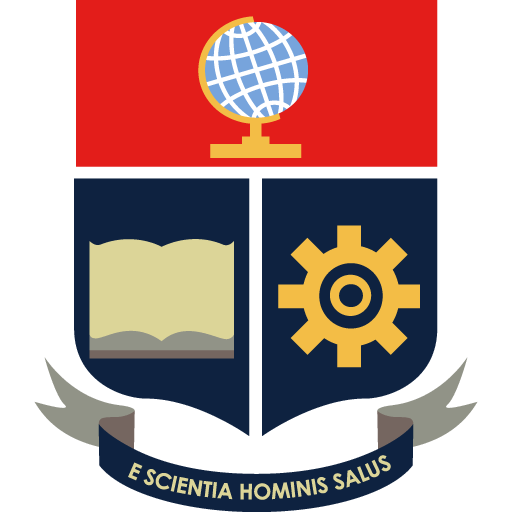

# **Cambio de Formación**

 
ind1=1;
t_sim2=100;
if server.NumBytesAvailable~=0
data=read(server,server.NumBytesAvailable,"uint8");
option=data(length(data));
end

### `Formas de posiciones`

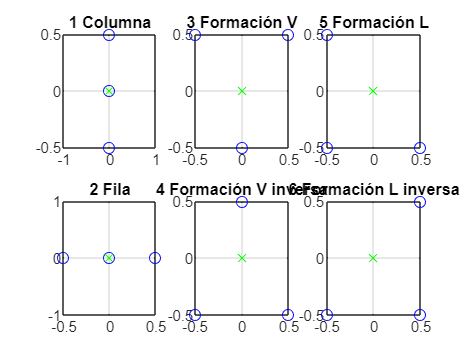

figure
subplot(2,3,1)
plot(0,d,'bo',0,0,'bo',0,-d,'bo',0,0,'gx')
title('1 Columna')
grid on
subplot(2,3,4)
plot(d,0,'bo',0,0,'bo',-d,0,'bo',0,0,'gx')
title('2 Fila')
grid on
%V
subplot(2,3,2)
plot(d,d,'bo',-d,d,'bo',0,-d,'bo',0,0,'gx')
title('3 Formación V')
grid on
subplot(2,3,5)
plot(d,-d,'bo',-d,-d,'bo',0,d,'bo',0,0,'gx')
title('4 Formación V inversa')
grid on
%L
subplot(2,3,3)
plot(-d,d,'bo',-d,-d,'bo',d,-d,'bo',0,0,'gx')
title('5 Formación L')
grid on
subplot(2,3,6)
plot(-d,-d,'bo',d,d,'bo',d,-d,'bo',0,0,'gx')
title('6 Formación L inversa')
grid on

### `Cambio de forma`

Opciones de formación:

1.- Columna

2.- Fila

3.- Formación V

4.- Formación V inversa

5.- Formación L

6.- Formación L inversa

Simulación iniciada


Simulación terminada en:


tiempo = 80.6500

tiempoROS = 15.3990

Trayectoria de la formación


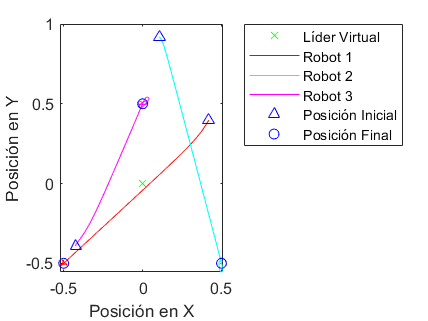

El error al realizar la formación es de: 1.280


Simulación iniciada


Simulación terminada en:


tiempo = 78.4400

tiempoROS = 14.5450

Trayectoria de la formación


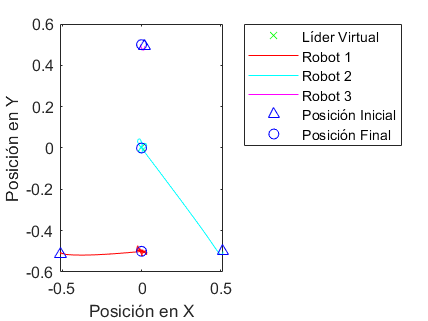

El error al realizar la formación es de: 0.987


while option ~=4 %open
    %lectura del gesto
    if server.NumBytesAvailable~=0
    data=read(server,server.NumBytesAvailable,"uint8");
    option=data(length(data));
    switch option
        case 1
            gesim="1.png";gesto="Gesto - Wave out";
        case 2
            gesim="2.png";gesto="Gesto - Wave in";
        case 3
            gesim="3.png";gesto="Gesto - Fist";
        case 4
            gesim="4.png";gesto="Gesto - Open";
        case 5
            gesim="5.png";gesto="Gesto - Pinch";
        otherwise
            gesim="6.png";gesto="Relajado - No Gesture";
    end
            %d es la distancia que puede tener cada agente respecto al Lider Virtual
%             if option==5&&antop~=5%Pinch
%                 if d==0.5
%                     d=1.0;
%                 else
%                     d=0.5;
%                 end
%             end
%          antop=option;
    end
    %fin de lectura del gesto

open('FormationControl.slx')
vars=sim('FormationControl');
option=vars.option(length(vars.option));
rx1=vars.h(:,1); rx1=rx1(length(rx1));
ry1=vars.h(:,2); ry1=ry1(length(ry1));
rx2=vars.h(:,3); rx2=rx2(length(rx2));
ry2=vars.h(:,4); ry2=ry2(length(ry2));
rx3=vars.h(:,5); rx3=rx3(length(rx3));
ry3=vars.h(:,6); ry3=ry3(length(ry3));
d=vars.d(length(vars.d));
form=vars.form(length(vars.form));

if option==3%Fist
    
%     if ant~=form||antd~=d
%         ant=form;
%         antd=d;
%         
        disp("Simulación iniciada")
        simform=sim("Mtest6.slx");
        disp("Simulación terminada en:")
        tiempo=simtime(length(simtime))
        tiempoROS=rostime(length(rostime))-rostime(1)    
%         Resultados:
        run results_op1.m
% %         Velocidades:
% %         figure
% %         subplot(3,1,1)
% %         plot(Vel1(1),Vel1(2)); plot(Vel1mod)
% %         subplot(3,1,2)
%     end
    %fin de cambio de formación
end

%fin de contenido de while
end

% empezar otro while para mostrar resultados o regresar a menu

ant=0;
antd=0;
antop=0;
aux=0;
open("menu.mlx")


% function printStatus (d,ind1)
%      if ind1 == 1
%          % The very first time we don't need to delete the old text
% %          fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b');
%          fprintf('Distancia entre los agentes de: ');
%          fprintf('%s [m]\b\b\b\b\b\b\b', num2str(d));
%      else
%         % Each \b removes one character from the previous fprintf.
%         fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b');
%         fprintf('%s [m]', num2str(d));
% %         fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\bDistancia entre los agentes de: %s [m]', num2str(d));
%      end
% end
